# Identification of vehicles' parameters from the bridge vibration response

## Summary

This example file illustrates the automated identification of key vehicle characteristics from vibration data collected on a suspension bridge.  The numerical implementation is based on ref. [1]. The bridge is modelled using a continuum model to reduce the computational cost associated with the identification of the vehicles. In this example, the bridge modal parameters are computed as in [2]. Vehicles are modelled as moving-masses to reduce the computational cost. In the following, only the vertical motion of the main span is modelled. This algorithm is suited to bridges in remote areas with little traffic.

To identify if and when a vehicle crosses the bridge, the following steps are considered [1]:

- The background response, i.e. the quasi-static response of the bridge deck is isolated from its resonant response. This is done using a zero-phase digital low-pass and high-pass fifth-order Butterworth filters. These filters are successively applied. A band-pass filter may be too unstable here for the range of frequencies considered.

- An outlier analysis is conducted to isolate the spikes associated with the passage of vehicles. This also gives a first estimate of the time at which a vehicle crosses the bridge.

- A clustering algorithm is applied to associate each group of outliers to a vehicle.

- Once each cluster is identified, the filtered displacement histories are cut into several segments, each of them centred around one cluster.

- For each segment, the normalized bridge response is fitted by a moving-mass model to estimate the vehicle speed and arrival time.

- One the arrival time and vehicle speed is known, its mass is estimated by applying a new fitting to the non-normalized response

**References**

[1] [Cheynet, E., Daniotti, N., Jakobsen,  J. B., & Snæbjörnsson, J. (2020). Improved long‐span bridge modeling using data‐driven identification of vehicle‐induced vibrations. Structural Control and Health Monitoring, volume 27, issue 9](https://doi.org/10.1002/stc.2398).

[2]  [https://se.mathworks.com/matlabcentral/fileexchange/51815-calculation-of-the-modal-parameters-of-a-suspension-bridge](https://se.mathworks.com/matlabcentral/fileexchange/51815-calculation-of-the-modal-parameters-of-a-suspension-bridge)

[3]  E.  Cheynet. ECheynet/EigenBridge v3.3. Zenodo, 2020, doi:10.5281/ZENODO.3817982.

## Generation of the bridge response to multiple vehicles

### Initialisation

clearvars;close all;clc
clf;close all;

Nyy = 446; % Number of nodes to discretize the bridge structure. We need a spatial resolution of 1 m in our case.
Nmodes = 6; % number of modes for each degree of freedoms, i.e. a total of 3x6 =18 nodes
[Bridge] = LysefjordBridge(Nyy); % bridge structural properties

[wn,phi] = eigenBridge(Bridge,Nmodes); % get the eigen frequencies and mode shapes [2,3]
fn=wn/(2*pi); % get the frequencies in Hz
zetaStruct = 5e-3*ones(3,Nmodes); % modal damping ratios


% Define the structure bridge
Bridge.zetaStruct = zetaStruct;
Bridge.wn = 2*pi*fn;
Bridge.phi = phi;


### Sampling parameters

fs = 15; % sampling frequency
M = 15; %  M must be a power of 2
[t,f] = getSamplingPara(M,fs);

Duration of target time series is 0.607 hours, i.e. 2.18e+03 sec 



N=numel(t);

### Wind turbulence

% No wind in this example
tmax = t(end);
Wind.u = zeros(Nyy,N);
Wind.w = zeros(Nyy,N);
Wind.t = t;

## Computation of the vehicle-induced response at midspan (target data)

The records from an accelerometer are simulated. These data are the "target" ones, i.e. they include the vehicles' parameters that will be identified separately. The bridge response is simulated at midspan only. In ref. [1], using records from the midspan only is observed to be an appropriate choice. No eigenfrequency or damping is defined for the vehicle, which is modelled as a moving mass. 

yTarget = Bridge.L/2; % midspan
[~,indY]=min(abs(Bridge.x.*Bridge.L-yTarget)); % get indice where the midspan is located 
Nvehicle = 4; % Number of vehicle selected
tic
%Create the structure variable vehicle_Target that contains the aprameters
%of each vehicle
rng(1) % To ensure reproducibility of this example
clear vehicleTarget
for ii=1:Nvehicle
    vehicleTarget(ii).mass = randi([1e3 50e3],1); % mass of the vehicle (kg)
    vehicleTarget(ii).speed = randi([30 80],1)/3.6; % speed of the vehicle (m/s)
    vehicleTarget(ii).direction = 1; % All the vehicle have the same direction. If "-1", the vehicle is moving in the opposite direction
    vehicleTarget(ii).tStart = 55+ii.*400; % arrival time (sec). t = 0s is the initial time of the simulation.  
end

% Compute the wind and vehicle-induced bridge response
% Newmark-beta algorithm is used for the solver
[Do1,Ao1] = dynaResp_vehicle_TD(Bridge,Wind,'vehicle',vehicleTarget); 

movingLoad model used 


% Get the vertical bridge displacement response at midspan
rz = squeeze(Do1(2,indY,:));
% Some white noise is added to challenge the identification algorithm
rz = rz + 0.03*std(rz).*randn(size(rz));
toc

Elapsed time is 86.242336 seconds.


### Visualization of the vehicle-induced response at midspan

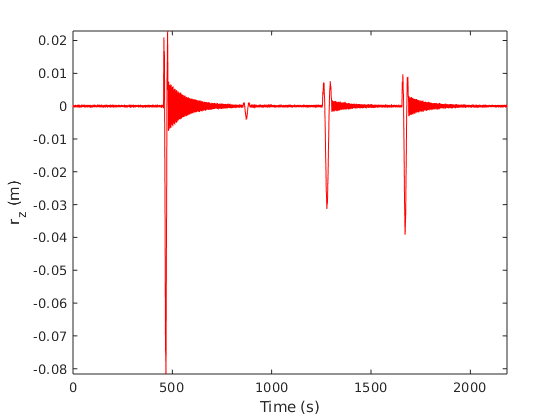

gcf;close all;
figure
plot(t,rz,'r')
xlabel('Time (s)')
ylabel('r_z (m)')
set(gcf,'color','w')
axis tight

## Identification of the parameters of the vehicles

The simulated vibrations responses are assumed to include an unknown number of vehicle with unknown mass, speed and arrival times. Here, the speed and speed and arrival time of each vehicle is estimated by isolating the response from each vehicle and by looking at the quasi-static vertical response of the bridge at midspan. The quasi-static component is also called background response and is located in the frequency range below the first vertical mode of vibration. In the present case, these frequencies are below 0.15 Hz. To keep the simulation real, the frequencies below 0.04 Hz are also filtered out as in a real situation, accelerometers record very-low-frequency components with poor accuracy. In practice, it depends on the quality of the accelerometer. A frequency of 0.04 Hz is a realistic value below which one can consider that the accelerometer records are too poor to be exploited.

### Outlier-detection algorithm and clustering algorithm

This step isolates the background response and identify the number of vehicles crossing the bridge.

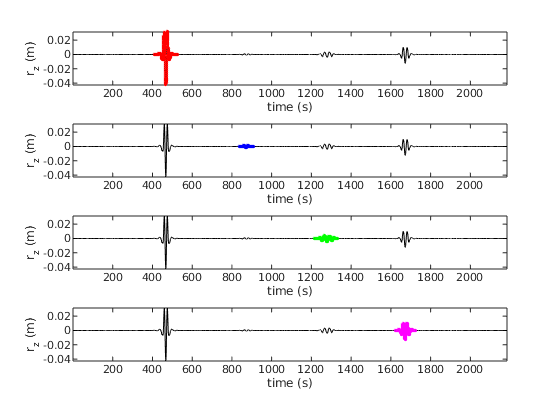

tSim = t;
minNp = 30; % minimum number of cluster points
CO = 30*fs; % cutoff value for the clusters, constructed using a hierarchical cluster tree (cf Matlab function "cluster")
fMin = 0.04; % cut-off frequency (high pass filter) -> must be above the lower frequency correctly measured by the accelerometer
fMax = 0.15; % cut-off frequency (low pass filter) -> must be lower than the first eigen frequency. here the lowest vertical eigenfrequency is 0.21 Hz
[rz_filtered,t_filtered,tImpact_guess,tCluster,rzCluster] = findVehicleID(rz,t,...
    'minNp',minNp,'CuttOff',CO,'deltaTmax',inf,'fcLow',fMin,'fcUp',fMax);
% tImpact_guess is the Initial guess estimate based on the cluster analysis
% rz_filtered,t_filtered, tCluster and rzCluster are used only for visualization purpose!

Ncluster = numel(tCluster);

clf;close all;
figure
COLOR = {'r','b','g','m','c','y'};
if Ncluster>numel(COLOR), COLOR = repmat(COLOR,1,Ncluster); end
for ii=1:Ncluster
    subplot(Ncluster,1,ii)
    plot(t_filtered,rz_filtered,'k')
    hold on
    box on
    plot(tCluster{ii},rzCluster{ii},'o','color',COLOR{ii},'markersize',2)
    xlabel('time (s)')
    ylabel('r_z (m)')
    axis tight
end

set(gcf,'color','w')

### Identification of the vehicles' arrival time and speed

This is the most time-consuming part of the algorithm: the identification of each vehicle takes typically one to three minutes.

Elapsed time is 79.534904 seconds.


Elapsed time is 53.524513 seconds.
Elapsed time is 27.881589 seconds.


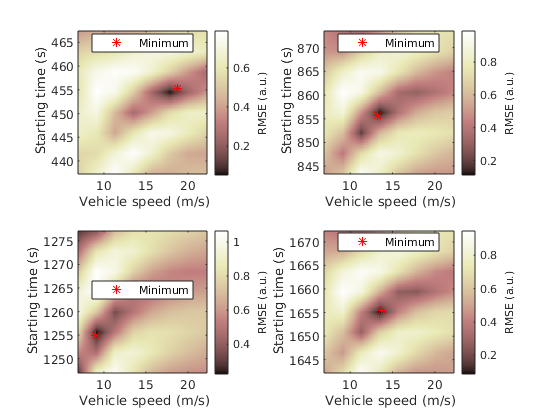

Elapsed time is 48.934510 seconds.


gradS = 0.3; % termination tolerance for the speed estimate, i.e. the speed is identified at +/- gradS (in m/s)
gradT = 0.5; % termination tolerance for the arrival time estimate, i.e. it is identified at +/- gradT (in s)
newN = 150; % number of data point for the time-domain simulation: less points means faster algorithm but also less accurate one
posAcc = yTarget./Bridge.L; % relative position of the accelerometer
tic
[vehicleSpeed,tImpact] = findSpeed(Bridge,t,rz,posAcc,tImpact_guess,...
    'gradS',gradS,'gradS',gradT,'newN',newN,'fcLow',fMin,'fcUp',fMax);

toc

Elapsed time is 50.010358 seconds.


fprintf('Target speed (km/h): \n')

Target speed (km/h): 


fprintf([repmat('%2.1f \t',1,Nvehicle),' \n'],[vehicleTarget(:).speed]*3.6)

66.0 	45.0 	34.0 	47.0 	 


fprintf('identified speed (km/h): \n')

identified speed (km/h): 


fprintf([repmat('%2.1f \t',1,Nvehicle),' \n'],[vehicleSpeed]*3.6)

67.4 	47.6 	32.5 	49.4 	 



fprintf('Target arrival time (s): \n')

Target arrival time (s): 


fprintf([repmat('%2.1f \t',1,Nvehicle),' \n'],[vehicleTarget(:).tStart])

455.0 	855.0 	1255.0 	1655.0 	 


fprintf('identified arrival time (s): \n')

identified arrival time (s): 


fprintf([repmat('%2.1f \t',1,Nvehicle),' \n'],[tImpact])

455.2 	855.8 	1255.0 	1655.5 	 


### Identification of the vehicles' mass

This is relatively straightforward since only one parameter needs to be identified

RMSE value is 0.017. 


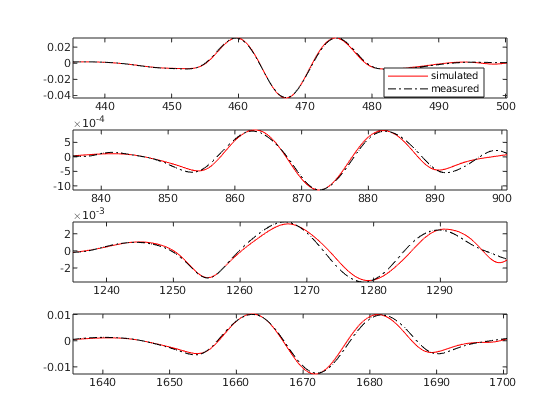

RMSE value is 0.073. 
RMSE value is 0.11. 
RMSE value is 0.062. 


[vehicleMass] = findMass(Bridge,t,rz,posAcc,tImpact,vehicleSpeed,'fcLow',fMin,'fcUp',fMax);

fprintf('Target mass (kg): \n')

Target mass (kg): 


fprintf([repmat('%4.0f \t',1,Nvehicle),' \n'],[vehicleTarget(:).mass])

21434 	1005 	8191 	10126 	 


fprintf('identified mass (kg): \n')

identified mass (kg): 


fprintf([repmat('%4.0f \t',1,Nvehicle),' \n'],[vehicleMass])

21312 	 915 	8843 	9460 	 


## Comparison between the target and simulated bridge response histories

TIme series visualization of the "measured" response to the traffic loading and the computed one, after fitting of the vehicle parameters

% Create a structure vehicle with the identified parameters of the vehicles.
clear vehicle
Nvehicle = numel(vehicleSpeed);
for ii=1:Nvehicle
    vehicle(ii).mass = abs(vehicleMass(ii));
    vehicle(ii).speed = vehicleSpeed(ii);
    vehicle(ii).direction = 1;
    vehicle(ii).tStart = tImpact(ii);
    vehicle(ii).wn = 0;
end

% COmpute the relative erros on the identified mas, speed and arrival time
errSpeed = nanmean(100.*([vehicle(:).speed]./[vehicleTarget(:).speed]-1));
errMass = nanmean(100.*([vehicle(:).mass]./[vehicleTarget(:).mass]-1));
errTime = nanmean(100.*([vehicle(:).tStart]./[vehicleTarget(:).tStart]-1));
fprintf(['Relative average error on speed: ',num2str(errSpeed,2),' percent \n'])

Relative average error on speed: 2.2 percent 


fprintf(['Relative average error on speed: ',num2str(errMass,2),' percent \n'])

Relative average error on speed: -2 percent 


fprintf(['Relative average error on speed: ',num2str(errTime,2),' percent \n'])

Relative average error on speed: 0.042 percent 



% Compute the bridge response with the identified vehicle parameters
[Do2] = dynaResp_vehicle_TD(Bridge,Wind,'vehicle',vehicle); % both wind and traffic

movingLoad model used 


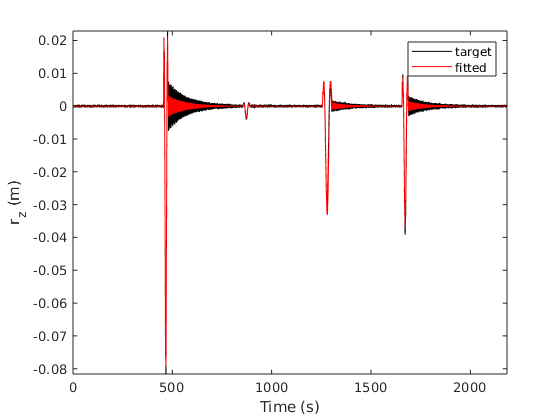

rzFit = squeeze(Do2(2,indY,:));

clf;close all;
figure
plot(t,rz,'k',t,rzFit,'r');
legend('target','fitted')
axis tight
xlabel('Time (s)')
ylabel('r_z (m)')
set(gcf,'color','w')
axis tight

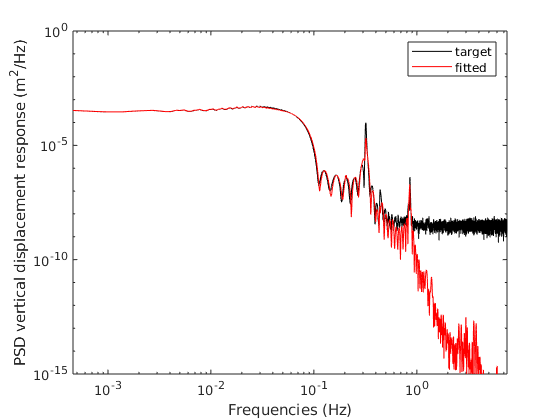


% PSD calculation
[S1,f1] = pmtm(rz,7,numel(rz),fs);
[S2,f2] = pmtm(rzFit,7,numel(rz),fs);
figure
loglog(f1,S1,'k',f2,S2,'r');
legend('target','fitted')
axis tight
ylim([1e-15,1])
xlabel('Frequencies (Hz)')
ylabel('PSD vertical displacement response (m^2/Hz)')

set(gcf,'color','w')




